Reading New Axion Systems file: TUBA (wells D)

[files,path] = uigetfile('*.raw*',  'Select file for plotting','MultiSelect','off');
if isequal(files,0)
    error('Error in file selection!');
end
TargetRawFile=[path files];

disp('Data loading completed successfully.');

Data loading completed successfully.


addpath(genpath('S:\met_narkilahti_neuro_sto-3700\MEA_data_internship\Lorenzo\AxionFileInput'))
AxisFileData = AxisFile(TargetRawFile);
voltageScale = AxisFileData.DataSets.VoltageScale;
SamplingFrequency = AxisFileData.DataSets.SamplingFrequency;

recordings = struct;   % Final container

prompt = {'Insert desired wells separated by space (e.g. A1 B2 or A):'};
dlgtitle = 'Select Wells';
dims = [1 60];

answer = inputdlg(prompt, dlgtitle, dims);

if isempty(answer)
    error('No wells selected. Operation cancelled.');
end

channels = AxisFileData.ChannelArray.Channels;

allWells = cell(length(channels),1);

for i = 1:length(channels)
    rowLetter = char('A' + channels(i).WellRow - 1);
    wellNumber = channels(i).WellColumn;
    allWells{i} = [rowLetter num2str(wellNumber)];
end

userInput = upper(strtrim(answer{1}));
tokens = strsplit(userInput);

selectedWells = {};

for i = 1:length(tokens)
    
    token = tokens{i};
    
    % If token is a single letter → load entire row
    if length(token) == 1 && isletter(token)
        
        rowLetter = token;
        
        matchingWells = availableWells( ...
            startsWith(availableWells, rowLetter));
        
        selectedWells = [selectedWells matchingWells];
        
    else
        selectedWells{end+1} = token;
    end
end

selectedWells = unique(selectedWells);

%% Print selected wells
fprintf('\nWells selected:\n');


Wells selected:


fprintf('%s ', selectedWells{:});

D1 


channels = AxisFileData.ChannelArray.Channels; % extraction of channel properties (WellRow, WellColumn, ElectrodeRow, ElectrodeColumn)

tic
for w = 1:length(selectedWells)

    currentWell = selectedWells{w};

    % Find channels belonging to this well
    idxWell = arrayfun(@(c) ...
        strcmp([char('A'+c.WellRow-1) num2str(c.WellColumn)], currentWell), ...
        channels); %row number became letter ex. 1 --> A

    wellChannels = channels(idxWell); %%keep only channels belonging to the current well

    % Reconstruct all electrodes for this well (reconstruction of names)
    Electrodes = {};
    for k = 1:length(wellChannels)
        elec = [num2str(wellChannels(k).ElectrodeRow) ...
                num2str(wellChannels(k).ElectrodeColumn)];
        Electrodes{end+1} = elec;
    end

    Electrodes = unique(Electrodes);

    for e = 1:length(Electrodes)
        currentElectrode = Electrodes{e};
        try
            % Try loading data directly
            Data = AxisFileData.RawVoltageData.LoadData(currentWell, currentElectrode);
        catch
            warning('Well %s or Electrode %s does not exist. Skipping.', ...
                    currentWell, currentElectrode);
            continue
        end

        address = find(~cellfun(@isempty, Data));

        if isempty(address)
            warning('No data found for Well %s Electrode %s. Skipping.', ...
                    currentWell, currentElectrode);
            continue
        end

        % Extract and scale voltage
        Voltagedata = double(Data{address}.Data) * voltageScale;
        Voltagedata = Voltagedata';

        % Store in structured format
        electrodeField = ['E' currentElectrode];
        recordings.(currentWell).(electrodeField) = Voltagedata;

    end
end
toc

Elapsed time is 258.837535 seconds.


Reading Older Axion File

%% Select OLD Axion file

[files_old,path_old] = uigetfile('*.raw*', ...
    'Select OLD Axion file','MultiSelect','off');

if isequal(files_old,0)
    error('Error in OLD file selection!');
end

TargetRawFile_old = [path_old files_old];

disp('Old Axion data loading completed successfully.');

Old Axion data loading completed successfully.


AxisFileData_old = AxisFile(TargetRawFile_old);
voltageScale_old = AxisFileData_old.DataSets.VoltageScale;
SamplingFrequency_old = AxisFileData_old.DataSets.SamplingFrequency;

recordings_old = struct;   % Final container for OLD system

prompt = {'Insert desired wells separated by space (e.g. A1 B2 or A):'};
dlgtitle = 'Select Wells (OLD Axion)';
dims = [1 60];

answer_old = inputdlg(prompt, dlgtitle, dims);

if isempty(answer_old)
    error('No wells selected. Operation cancelled.');
end

channels_old = AxisFileData_old.ChannelArray.Channels;

allWells_old = cell(length(channels_old),1);

for i = 1:length(channels_old)
    rowLetter = char('A' + channels_old(i).WellRow - 1);
    wellNumber = channels_old(i).WellColumn;
    allWells_old{i} = [rowLetter num2str(wellNumber)];
end

availableWells_old = unique(allWells_old);

userInput_old = upper(strtrim(answer_old{1}));
tokens_old = strsplit(userInput_old);

selectedWells_old = {};

for i = 1:length(tokens_old)
    
    token = tokens_old{i};
    
    % If token is a single letter → load entire row
    if length(token) == 1 && isletter(token)
        
        rowLetter = token;
        
        matchingWells = availableWells_old( ...
            startsWith(availableWells_old, rowLetter));
        
        selectedWells_old = [selectedWells_old matchingWells];
        
    else
        selectedWells_old{end+1} = token;
    end
end

selectedWells_old = unique(selectedWells_old);

%% Print selected wells
fprintf('\nWells selected (OLD system):\n');


Wells selected (OLD system):


fprintf('%s ', selectedWells_old{:});

F2 

tic
for w = 1:length(selectedWells_old)

    currentWell = selectedWells_old{w};

    % Find channels belonging to this well
    idxWell = arrayfun(@(c) ...
        strcmp([char('A'+c.WellRow-1) num2str(c.WellColumn)], currentWell), ...
        channels_old);

    wellChannels = channels_old(idxWell); %% keep only channels belonging to the current well

    % Reconstruct all electrodes for this well
    Electrodes = {};
    for k = 1:length(wellChannels)
        elec = [num2str(wellChannels(k).ElectrodeRow) ...
                num2str(wellChannels(k).ElectrodeColumn)];
        Electrodes{end+1} = elec;
    end

    Electrodes = unique(Electrodes);

    for e = 1:length(Electrodes)

        currentElectrode = Electrodes{e};

        try
            % Try loading data directly
            Data = AxisFileData_old.RawVoltageData.LoadData(currentWell, currentElectrode);
        catch
            warning('Well %s or Electrode %s does not exist. Skipping.', ...
                    currentWell, currentElectrode);
            continue
        end

        address = find(~cellfun(@isempty, Data));

        if isempty(address)
            warning('No data found for Well %s Electrode %s. Skipping.', ...
                    currentWell, currentElectrode);
            continue
        end

        % Extract and scale voltage
        Voltagedata = double(Data{address}.Data) * voltageScale_old;
        Voltagedata = Voltagedata';

        % Store in structured format
        electrodeField = ['E' currentElectrode];
        recordings_old.(currentWell).(electrodeField) = Voltagedata;

    end
end
toc

Elapsed time is 1188.572737 seconds.


Analysis

%% Base folders

lorenzoFolder = 'S:\met_narkilahti_neuro_sto-3700\MEA_data_internship\Lorenzo';

if ~exist(lorenzoFolder,'dir')
    mkdir(lorenzoFolder);
end

baseFolder = fullfile(lorenzoFolder,'OldVSNew');

if ~exist(baseFolder,'dir')
    mkdir(baseFolder);
end

%% Subfolders for the different analyses

rawPsdFolder = fullfile(baseFolder,'Raw_PSD');
lfpPsdFolder = fullfile(baseFolder,'LFP_PSD');


if ~exist(rawPsdFolder,'dir')
    mkdir(rawPsdFolder);
end

if ~exist(lfpPsdFolder,'dir')
    mkdir(lfpPsdFolder);
end

RAW PSD

In this section, the Power Spectral Density (PSD) of the raw signals is computed for each electrode using Welch’s method. This method estimates the frequency content of a signal by dividing it into overlapping segments, applying a Hamming window to each segment, computing the Fourier transform, and then averaging the resulting spectra. This approach reduces the variance of the spectral estimate and provides a more stable representation of how signal power is distributed across frequencies.

For each well, the PSD is calculated separately for all electrodes. The spectra are then restricted to the frequency range of interest (up to 3000 Hz in this case) and stored in a matrix where each column corresponds to one electrode. Finally, the PSDs from all electrodes within the same well are averaged to obtain a mean spectrum representing the overall spectral characteristics of that well.

The same procedure is applied to recordings from both the OLD and the NEW acquisition systems, allowing a direct comparison of their spectral properties.

%% PSD Parameters
window_psd   = hamming(4096);
noverlap_psd = 2048;
nfft_psd     = 8192;

outputFolder = rawPsdFolder;

nWells = min(length(selectedWells_old), length(selectedWells));

for w = 1:nWells

    well_old = selectedWells_old{w};
    well_new = selectedWells{w};

    %% -------- OLD RECORDINGS --------

    electrodes_old = fieldnames(recordings_old.(well_old));
    psd_old = [];

    for e = 1:length(electrodes_old)

        data = recordings_old.(well_old).(electrodes_old{e});

        [pxx,f] = pwelch(data,window_psd,noverlap_psd,nfft_psd,SamplingFrequency);

        idx = f <= 3000;

        psd_old(:,e) = pxx(idx);

    end

    mean_psd_old = mean(psd_old,2);

    %% -------- NEW RECORDINGS --------

    electrodes_new = fieldnames(recordings.(well_new));
    psd_new = [];

    for e = 1:length(electrodes_new)

        data = recordings.(well_new).(electrodes_new{e});

        [pxx,~] = pwelch(data,window_psd,noverlap_psd,nfft_psd,SamplingFrequency);

        psd_new(:,e) = pxx(idx);

    end

    mean_psd_new = mean(psd_new,2);

    %% -------- PSD OLD --------

   fig1 = figure;
    hold on
    
    nElec_old = length(electrodes_old);
    colors = lines(nElec_old);
    
    for e = 1:nElec_old
        plot(f(idx),10*log10(psd_old(:,e)),...
            'Color',colors(e,:),...
            'LineWidth',1,...
            'DisplayName',electrodes_old{e});
    end
    
    plot(f(idx),10*log10(mean_psd_old),...
        'k','LineWidth',3,...
        'DisplayName','Mean');
    
    legend show
    title(['RAW PSD OLD - Well ' well_old])
    xlabel('Frequency (Hz)')
    ylabel('Power (dB/Hz)')
    grid on
    
    exportgraphics(fig1,fullfile(outputFolder,...
        ['PSD_RAW_OLD_' well_old '.png']),'Resolution',300)
    
    close(fig1)

    %% -------- PSD NEW --------

    fig2 = figure;
    hold on
    
    nElec_new = length(electrodes_new);
    colors = lines(nElec_new);
    
    for e = 1:nElec_new
        plot(f(idx),10*log10(psd_new(:,e)),...
            'Color',colors(e,:),...
            'LineWidth',1,...
            'DisplayName',electrodes_new{e});
    end
    
    plot(f(idx),10*log10(mean_psd_new),...
        'k','LineWidth',3,...
        'DisplayName','Mean');
    
    legend show
    title(['RAW PSD NEW - Well ' well_new])
    xlabel('Frequency (Hz)')
    ylabel('Power (dB/Hz)')
    grid on
    
    exportgraphics(fig2,fullfile(outputFolder,...
        ['PSD_RAW_NEW_' well_new '.png']),'Resolution',300)
    
    close(fig2)

    %% -------- PSD COMPARISON --------

    fig3 = figure;
    hold on

    plot(f(idx),10*log10(mean_psd_old),'LineWidth',3)
    plot(f(idx),10*log10(mean_psd_new),'LineWidth',3)

    legend('OLD','NEW')

    title(['PSD Comparison - ' well_old ' vs ' well_new])
    xlabel('Frequency (Hz)')
    ylabel('Power (dB/Hz)')
    grid on

    exportgraphics(fig3,fullfile(outputFolder,...
        ['PSD_COMPARISON_' well_old '_' well_new '.png']),'Resolution',300)

    close(fig3)

end

LFP PSD

The code extracts the Local Field Potential (LFP) component from the raw electrophysiological recordings and computes the Power Spectral Density (PSD) for each electrode within every well.

First, a third-order low-pass Butterworth filter with a cutoff frequency of 250 Hz is designed to isolate the LFP band from the raw signal. The filtering is applied using the `filtfilt` function, which performs forward and reverse filtering to avoid phase distortion.

For each well, the code iterates through all available electrodes. The raw signal from each electrode is filtered to obtain the LFP signal. The Power Spectral Density of the filtered signal is then estimated using Welch’s method (`pwelch`). A Hamming window of 4096 samples with 50% overlap (2048 samples) and an FFT length of 8192 points is used to obtain a stable spectral estimate with adequate frequency resolution.

Only the frequency range up to 250 Hz is retained, corresponding to the LFP band. The PSD values are stored for each electrode, allowing the construction of a matrix containing the spectral power across frequencies and electrodes.

Each electrode PSD is plotted individually in decibels (10·log10 of the power). After processing all electrodes in the well, the mean PSD across electrodes is computed and plotted as a thick black dashed line to represent the average spectral profile of the well.

The resulting figure therefore shows:

- the PSD of each individual electrode

- the mean PSD across all electrodes in the well

Finally, the figure is saved to the specified output folder.

The same procedure is then repeated for the corresponding **OLD recordings**, producing analogous PSD plots for the older dataset before proceeding to the OLD vs NEW comparison.

%% Parameters for LFP extraction and plotting 
lfp_cut = 250;       % low-pass filter cutoff (Hz)
window_psd   = hamming(4096);
noverlap_psd = 2048;
nfft_psd     = 8192;

fs_raw = SamplingFrequency;

outputFolder = lfpPsdFolder;

% Design low-pass Butterworth filter
[b_lfp, a_lfp] = butter(3, lfp_cut/(fs_raw/2), 'low');

nWells = min(length(selectedWells), length(selectedWells_old));

for w = 1:nWells

    well_new = selectedWells{w};
    well_old = selectedWells_old{w};

    electrodeNames_new = fieldnames(recordings.(well_new));

    fig = figure; hold on;

    psd_all_new = [];
    lineHandles = gobjects(length(electrodeNames_new),1);

    for e = 1:length(electrodeNames_new)

        electrodeField = electrodeNames_new{e};
        data = recordings.(well_new).(electrodeField);

        % ---- LFP extraction ----
        lfp_clean = filtfilt(b_lfp, a_lfp, data);

        % ---- PSD ----
        [pxx_lfp, f_lfp] = pwelch(lfp_clean,...
                                  window_psd,...
                                  noverlap_psd,...
                                  nfft_psd,...
                                  fs_raw);

        idxLFP = f_lfp <= lfp_cut;

        psd_all_new(:,e) = pxx_lfp(idxLFP);

        % plot electrode PSD
        lineHandles(e) = plot(f_lfp(idxLFP),...
                              10*log10(pxx_lfp(idxLFP)),...
                              'LineWidth',1);

    end

    % mean PSD
    mean_psd_new = mean(psd_all_new,2);

    meanHandle = plot(f_lfp(idxLFP),...
                      10*log10(mean_psd_new),...
                      'k--','LineWidth',3);

    xlabel('Frequency (Hz)');
    ylabel('Power (dB/Hz)');
    title(['LFP PSD (<', num2str(lfp_cut),' Hz) - NEW Well ', well_new]);
    grid on;

    legend([lineHandles; meanHandle],...
           [electrodeNames_new; {'Mean'}],...
           'Location','bestoutside');

    exportgraphics(fig,fullfile(outputFolder,...
        ['PSD_LFP_NEW_' well_new '.png']),'Resolution',300);

    close(fig);





    electrodeNames_old = fieldnames(recordings_old.(well_old));

    fig = figure; hold on;

    psd_all_old = [];
    lineHandles = gobjects(length(electrodeNames_old),1);

    for e = 1:length(electrodeNames_old)

        electrodeField = electrodeNames_old{e};
        data = recordings_old.(well_old).(electrodeField);

        % LFP extraction
        lfp_clean = filtfilt(b_lfp, a_lfp, data);

        % PSD
        [pxx_lfp, ~] = pwelch(lfp_clean,...
                              window_psd,...
                              noverlap_psd,...
                              nfft_psd,...
                              fs_raw);

        psd_all_old(:,e) = pxx_lfp(idxLFP);

        % plot electrode PSD
        lineHandles(e) = plot(f_lfp(idxLFP),...
                              10*log10(pxx_lfp(idxLFP)),...
                              'LineWidth',1);

    end

    % mean PSD
    mean_psd_old = mean(psd_all_old,2);

    meanHandle = plot(f_lfp(idxLFP),...
                      10*log10(mean_psd_old),...
                      'k--','LineWidth',3);

    xlabel('Frequency (Hz)');
    ylabel('Power (dB/Hz)');
    title(['LFP PSD (<', num2str(lfp_cut),' Hz) - OLD Well ', well_old]);
    grid on;

    legend([lineHandles; meanHandle],...
           [electrodeNames_old; {'Mean'}],...
           'Location','bestoutside');

    exportgraphics(fig,fullfile(outputFolder,...
        ['PSD_LFP_OLD_' well_old '.png']),'Resolution',300);

    close(fig);

**OLD vs NEW PSD Comparison**

After computing the mean LFP power spectral density for both the NEW and OLD recordings, the code performs a direct comparison between the two conditions at the well level.

For each pair of corresponding wells, the mean PSD across electrodes previously computed for the OLD dataset and the mean PSD for the NEW dataset are plotted together in the same figure. The PSD values are expressed in decibels (10·log10 of the power) and displayed as a function of frequency within the LFP band (0–250 Hz).

The OLD condition is plotted as a thick blue line, while the NEW condition is plotted as a thick red line. This visualization allows a direct inspection of differences in spectral power across frequencies between the two recordings.

The resulting plot provides an overview of how the average LFP spectral profile of the well changes between the OLD and NEW datasets. The figure is then saved to the output directory for later inspection.

    fig = figure; hold on

    plot(f_lfp(idxLFP),...
         10*log10(mean_psd_old),...
         'b','LineWidth',3);

    plot(f_lfp(idxLFP),...
         10*log10(mean_psd_new),...
         'r','LineWidth',3);

    xlabel('Frequency (Hz)');
    ylabel('Power (dB/Hz)');
    title(['LFP PSD Comparison - OLD ',well_old,' vs NEW ',well_new]);
    grid on;

    legend(['OLD ' well_old], ['NEW ' well_new]);

    exportgraphics(fig,fullfile(outputFolder,...
        ['PSD_LFP_COMPARISON_' well_old '_' well_new '.png']),...
        'Resolution',300);

    close(fig);

 %%

**PSD Ratio (NEW vs OLD)**

To further quantify spectral differences between the two recordings, the code computes the frequency-wise ratio between the mean PSD of the NEW dataset and the mean PSD of the OLD dataset.

This ratio is calculated as: 10*log10(PSD_NEW/PSD_OLD)

which represents the difference in power between the two conditions expressed in decibels.

A value of:

- **0 dB** indicates identical spectral power between NEW and OLD,

- **positive values** indicate higher power in the NEW recordings,

- **negative values** indicate higher power in the OLD recordings.

The ratio is plotted as a function of frequency within the LFP band. A horizontal dashed line at 0 dB is added as a reference to facilitate the interpretation of power increases or decreases.

This representation highlights frequency ranges where the spectral power differs between the two datasets and allows a clearer identification of band-specific changes in LFP activity.

    psd_ratio_db = 10*log10((mean_psd_new + eps) ./ (mean_psd_old + eps));

    fig = figure;

    plot(f_lfp(idxLFP), psd_ratio_db, 'k','LineWidth',3);
    hold on
    yline(0,'--');

    xlabel('Frequency (Hz)');
    ylabel('Power Difference (dB)');
    title(['LFP PSD Ratio NEW/OLD - ',well_old,' vs ',well_new]);

    grid on

    exportgraphics(fig,fullfile(outputFolder,...
        ['PSD_LFP_RATIO_' well_old '_' well_new '.png']),...
        'Resolution',300);

    close(fig);

end

Band power values were computed for each electrode and subsequently summarized at the well level.

%% LFP Parameters
lfp_cut = 250;
fs_raw  = SamplingFrequency;

[b_lfp, a_lfp] = butter(3, lfp_cut/(fs_raw/2), 'low');

%% PSD parameters
window_psd   = hamming(4096);
noverlap_psd = 2048;
nfft_psd     = 8192;

%% Container
WellList      = {};
ElectrodeList = {};
SystemList    = {};

Delta_all     = [];
Theta_all     = [];
Alpha_all     = [];
Beta_all      = [];
LowGamma_all  = [];
HighGamma_all = [];
TotalLFP_all  = [];


New Axion System

for w = 1:length(selectedWells)

    currentWell = selectedWells{w};

    if ~isfield(recordings, currentWell)
        continue
    end

    electrodeNames = fieldnames(recordings.(currentWell));

    for e = 1:length(electrodeNames)

        electrodeField = electrodeNames{e};
        data = recordings.(currentWell).(electrodeField);

        % LFP
        lfp_clean = filtfilt(b_lfp, a_lfp, data);

        % PSD
        [pxx_lfp, f_lfp] = pwelch(lfp_clean, ...
                                  window_psd, ...
                                  noverlap_psd, ...
                                  nfft_psd, ...
                                  fs_raw);

        % Band powers
        Delta     = bandpower(pxx_lfp, f_lfp, [1 4],   'psd');
        Theta     = bandpower(pxx_lfp, f_lfp, [4 8],   'psd');
        Alpha     = bandpower(pxx_lfp, f_lfp, [8 13],  'psd');
        Beta      = bandpower(pxx_lfp, f_lfp, [13 30], 'psd');
        LowGamma  = bandpower(pxx_lfp, f_lfp, [30 55], 'psd');
        HighGamma = bandpower(pxx_lfp, f_lfp, [55 150],'psd');
        TotalLFP  = bandpower(pxx_lfp, f_lfp, [1 250], 'psd');

        % Store
        WellList{end+1,1}      = currentWell;
        ElectrodeList{end+1,1} = electrodeField;
        SystemList{end+1,1}    = 'NEW';

        Delta_all(end+1,1)     = Delta;
        Theta_all(end+1,1)     = Theta;
        Alpha_all(end+1,1)     = Alpha;
        Beta_all(end+1,1)      = Beta;
        LowGamma_all(end+1,1)  = LowGamma;
        HighGamma_all(end+1,1) = HighGamma;
        TotalLFP_all(end+1,1)  = TotalLFP;

    end
end


Old Axion System 


for w = 1:length(selectedWells_old)

    currentWell = selectedWells_old{w};

    if ~isfield(recordings_old, currentWell)
        continue
    end

    electrodeNames = fieldnames(recordings_old.(currentWell));

    for e = 1:length(electrodeNames)

        electrodeField = electrodeNames{e};
        data = recordings_old.(currentWell).(electrodeField);

        lfp_clean = filtfilt(b_lfp, a_lfp, data);

        [pxx_lfp, f_lfp] = pwelch(lfp_clean, window_psd, noverlap_psd, nfft_psd, fs_raw);

        Delta     = bandpower(pxx_lfp, f_lfp, [1 4],   'psd');
        Theta     = bandpower(pxx_lfp, f_lfp, [4 8],   'psd');
        Alpha     = bandpower(pxx_lfp, f_lfp, [8 13],  'psd');
        Beta      = bandpower(pxx_lfp, f_lfp, [13 30], 'psd');
        LowGamma  = bandpower(pxx_lfp, f_lfp, [30 55], 'psd');
        HighGamma = bandpower(pxx_lfp, f_lfp, [55 150],'psd');
        TotalLFP  = bandpower(pxx_lfp, f_lfp, [1 250], 'psd');

        WellList{end+1,1}      = currentWell;
        ElectrodeList{end+1,1} = electrodeField;
        SystemList{end+1,1}    = 'OLD';

        Delta_all(end+1,1)     = Delta;
        Theta_all(end+1,1)     = Theta;
        Alpha_all(end+1,1)     = Alpha;
        Beta_all(end+1,1)      = Beta;
        LowGamma_all(end+1,1)  = LowGamma;
        HighGamma_all(end+1,1) = HighGamma;
        TotalLFP_all(end+1,1)  = TotalLFP;

    end
end

%% ELECTRODE TABLE

BandPower_ElectrodeTable = table( ...
    WellList, ElectrodeList, SystemList, ...
    Delta_all, Theta_all, Alpha_all, Beta_all, ...
    LowGamma_all, HighGamma_all, TotalLFP_all, ...
    'VariableNames',{ ...
    'Well','Electrode','System', ...
    'Delta','Theta','Alpha','Beta', ...
    'LowGamma','HighGamma','TotalLFP'});

Well Level

To obtain well-level measures, the band power values were averaged across all electrodes belonging to the same well.To obtain well-level measures, the band power values were averaged across all electrodes belonging to the same well.

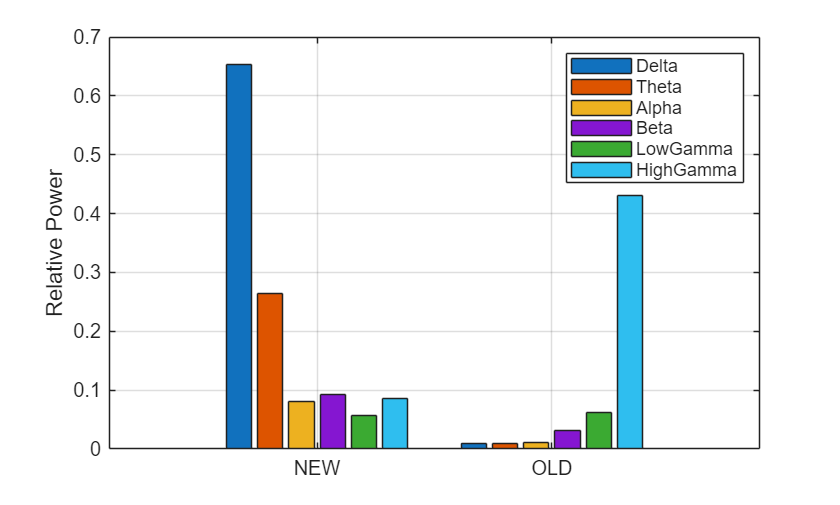

uniqueWells = unique(BandPower_ElectrodeTable.Well);

WellName   = {};
SystemName = {};

MeanDelta     = [];
MeanTheta     = [];
MeanAlpha     = [];
MeanBeta      = [];
MeanLowGamma  = [];
MeanHighGamma = [];
MeanTotalLFP  = [];

RelDelta      = [];
RelTheta      = [];
RelAlpha      = [];
RelBeta       = [];
RelLowGamma   = [];
RelHighGamma  = [];

for i = 1:length(uniqueWells)


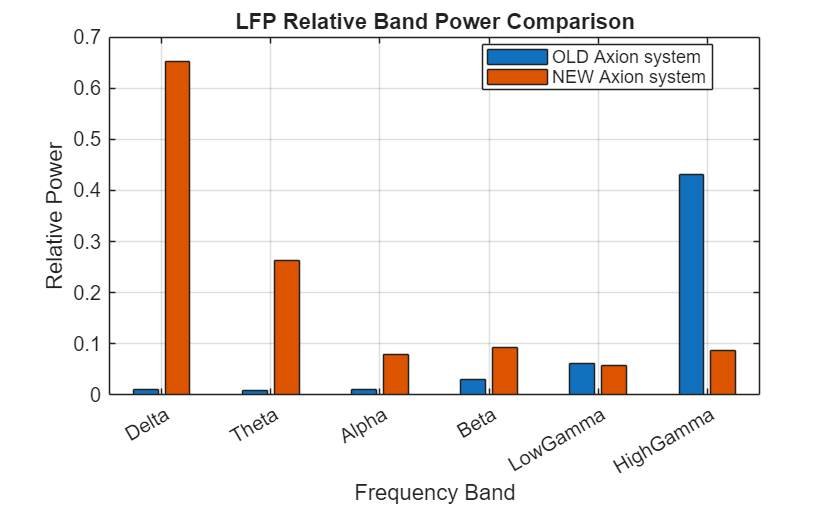

    thisWell = uniqueWells{i};
    idx = strcmp(BandPower_ElectrodeTable.Well, thisWell);
    thisSystem = BandPower_ElectrodeTable.System{find(idx,1)};

    % Mean absolute powers
    meanDelta     = mean(BandPower_ElectrodeTable.Delta(idx));
    meanTheta     = mean(BandPower_ElectrodeTable.Theta(idx));
    meanAlpha     = mean(BandPower_ElectrodeTable.Alpha(idx));
    meanBeta      = mean(BandPower_ElectrodeTable.Beta(idx));
    meanLowGamma  = mean(BandPower_ElectrodeTable.LowGamma(idx));
    meanHighGamma = mean(BandPower_ElectrodeTable.HighGamma(idx));
    meanTotal     = mean(BandPower_ElectrodeTable.TotalLFP(idx));

    % Relative powers
    relDelta     = meanDelta     / meanTotal;
    relTheta     = meanTheta     / meanTotal;
    relAlpha     = meanAlpha     / meanTotal;
    relBeta      = meanBeta      / meanTotal;
    relLowGamma  = meanLowGamma  / meanTotal;
    relHighGamma = meanHighGamma / meanTotal;

    % Store
    WellName{end+1,1}   = thisWell;
    SystemName{end+1,1} = thisSystem;

    MeanDelta(end+1,1)     = meanDelta;
    MeanTheta(end+1,1)     = meanTheta;
    MeanAlpha(end+1,1)     = meanAlpha;
    MeanBeta(end+1,1)      = meanBeta;
    MeanLowGamma(end+1,1)  = meanLowGamma;
    MeanHighGamma(end+1,1) = meanHighGamma;
    MeanTotalLFP(end+1,1)  = meanTotal;

    RelDelta(end+1,1)      = relDelta;
    RelTheta(end+1,1)      = relTheta;
    RelAlpha(end+1,1)      = relAlpha;
    RelBeta(end+1,1)       = relBeta;
    RelLowGamma(end+1,1)   = relLowGamma;
    RelHighGamma(end+1,1)  = relHighGamma;

end

%% Create WELL table


BandPower_WellTable = table( ...
    WellName, SystemName, ...
    MeanDelta, MeanTheta, MeanAlpha, MeanBeta, ...
    MeanLowGamma, MeanHighGamma, MeanTotalLFP, ...
    RelDelta, RelTheta, RelAlpha, RelBeta, ...
    RelLowGamma, RelHighGamma, ...
    'VariableNames',{ ...
    'Well','System', ...
    'MeanDelta','MeanTheta','MeanAlpha','MeanBeta', ...
    'MeanLowGamma','MeanHighGamma','MeanTotalLFP', ...
    'RelDelta','RelTheta','RelAlpha','RelBeta', ...
    'RelLowGamma','RelHighGamma'});

figure
bar(categorical(BandPower_WellTable.System), ...
    [BandPower_WellTable.RelDelta BandPower_WellTable.RelTheta ...
     BandPower_WellTable.RelAlpha BandPower_WellTable.RelBeta ...
     BandPower_WellTable.RelLowGamma BandPower_WellTable.RelHighGamma])

ylabel('Relative Power')
legend({'Delta','Theta','Alpha','Beta','LowGamma','HighGamma'})
grid on

BarPlots for relative band powers.

%% Select rows

NEW_idx = strcmp(BandPower_WellTable.System,'NEW');
OLD_idx = strcmp(BandPower_WellTable.System,'OLD');

%% Extract relative band powers

NEW_values = [
    BandPower_WellTable.RelDelta(NEW_idx)
    BandPower_WellTable.RelTheta(NEW_idx)
    BandPower_WellTable.RelAlpha(NEW_idx)
    BandPower_WellTable.RelBeta(NEW_idx)
    BandPower_WellTable.RelLowGamma(NEW_idx)
    BandPower_WellTable.RelHighGamma(NEW_idx)
];

OLD_values = [
    BandPower_WellTable.RelDelta(OLD_idx)
    BandPower_WellTable.RelTheta(OLD_idx)
    BandPower_WellTable.RelAlpha(OLD_idx)
    BandPower_WellTable.RelBeta(OLD_idx)
    BandPower_WellTable.RelLowGamma(OLD_idx)
    BandPower_WellTable.RelHighGamma(OLD_idx)
];

%% Combine data

data = [OLD_values NEW_values];

bands = {'Delta','Theta','Alpha','Beta','LowGamma','HighGamma'};

%% Plot

figure
bar(data)
set(gca,'XTickLabel',bands)
ylabel('Relative Power')
xlabel('Frequency Band')
legend({'OLD Axion system','NEW Axion system'},'Location','best')
title('LFP Relative Band Power Comparison')
grid on